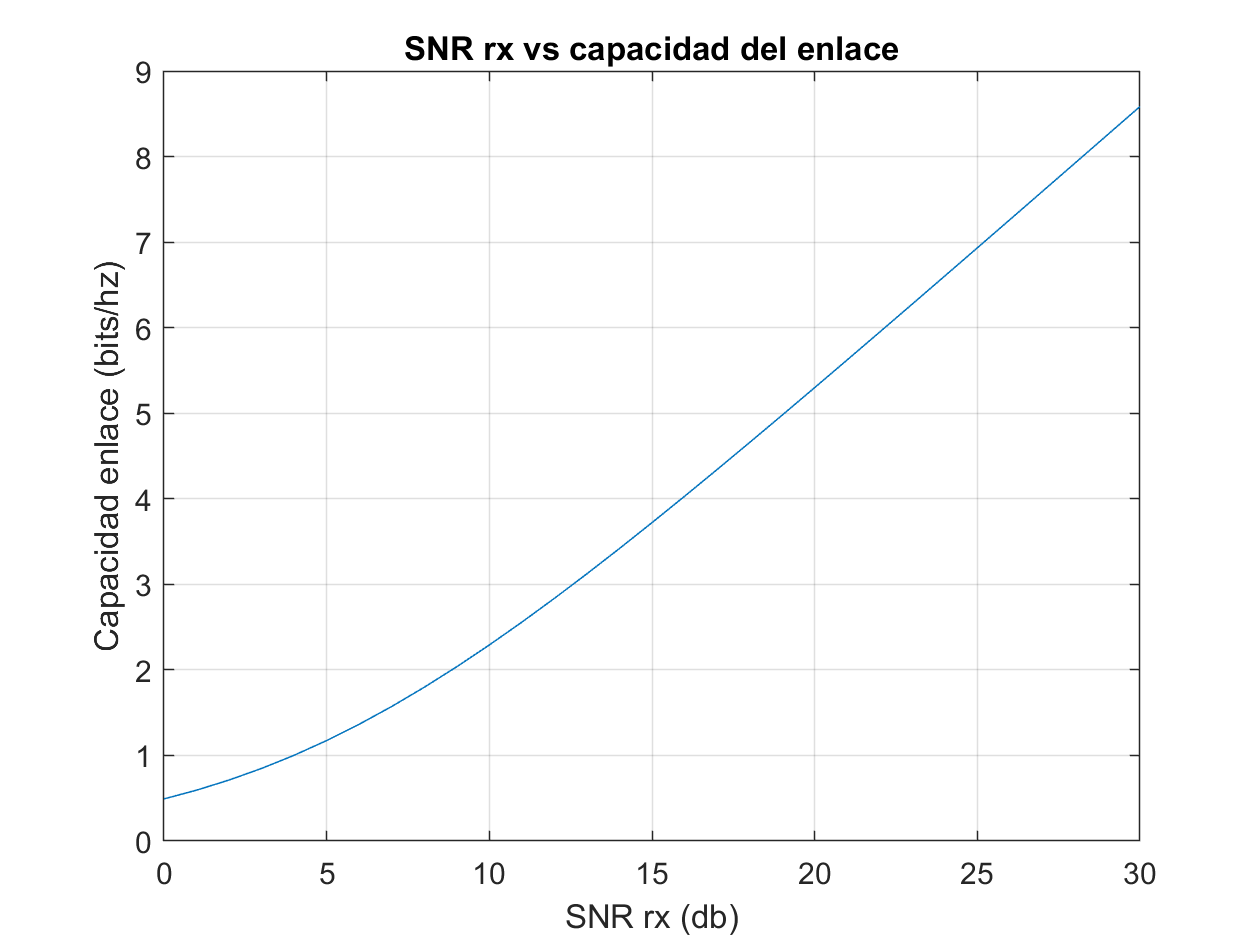

%% PRACTICA 3 MIMO

close all
clear
format compact
%% 
% 2. Sistema de referencia
% 
% Parametros

BW=1;
Po_tx=0;
SNR_rx= 0:30;
%H
% % % % % h_db=randi([1 7],1,100) -7;

h_db=-rand(1,100)*6;
%h=10.^(h/20);

%formula sistema tx-rx
% 0 (Po_tx) – L = S/N + N, 	en dB
%100 veces con distinta atenucion

c=zeros(1,length(SNR_rx));
%C=log(1+S/N)

%bucle snr_rx
for k=1:length(SNR_rx)
    SNR_iter=SNR_rx(k);
   % SNR_real_db= SNR_iter + h_db;  %valores de h son negativos por lo que SNR disminuye
    SNR_real_db= SNR_iter + h_db - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
    SNR_real=10.^((SNR_real_db/10));
    c=log2(1+ SNR_real);
    c_mean(k)=mean(c);
end

plot(SNR_rx, c_mean)
grid on
title ("SNR rx vs capacidad del enlace")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")

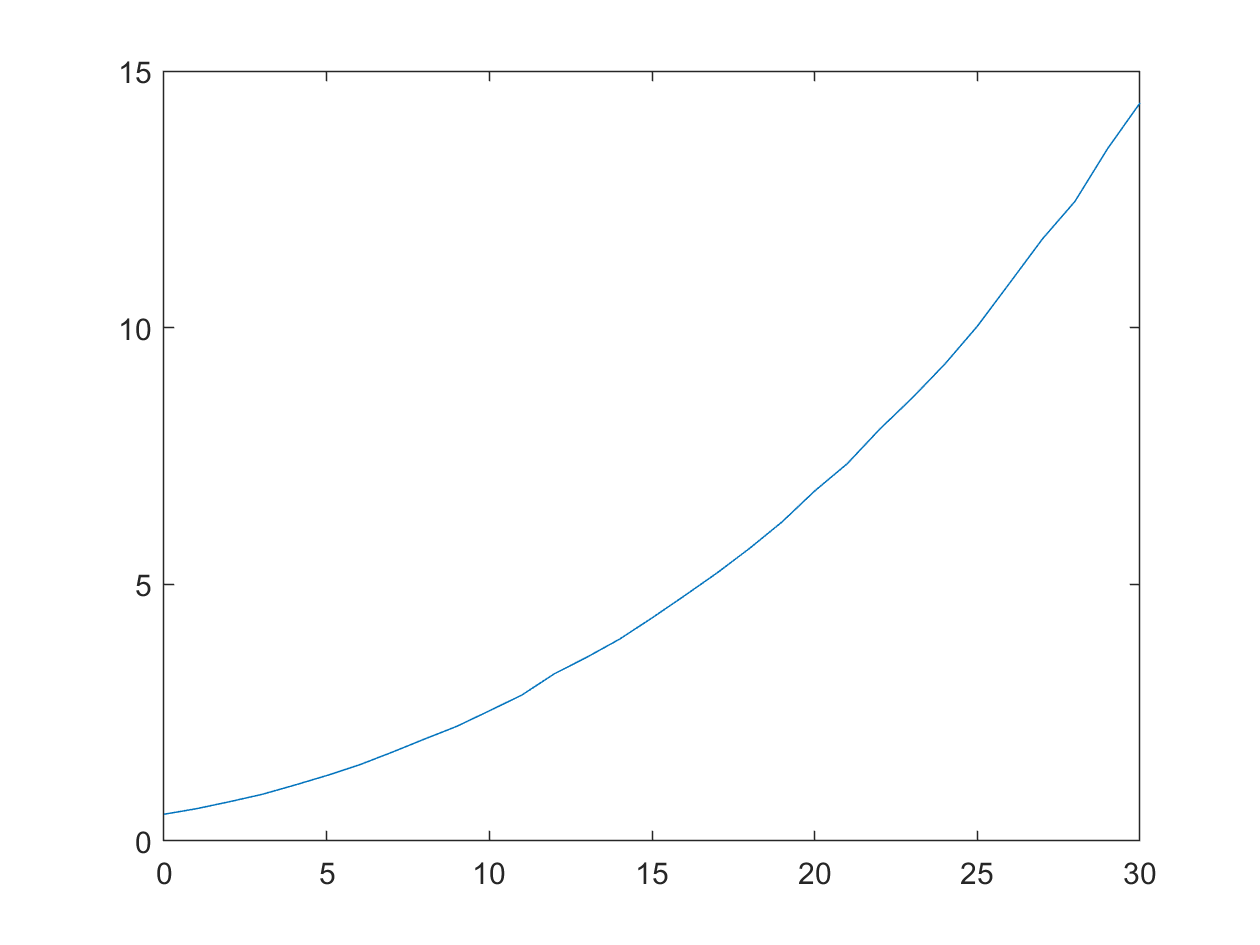

%% 
% 
%% 
% 3. PARAMETROS MIMO 
% 
% 16 combinaciones pero procesamos anres d tx y despues de rx. combina adecuadamente  
% conociendo H, para q el resultado sea una diagonal. y1=d1*x1
% 
% LTE extendiendo -> wifi.
% 
% 

Ni=4; %tx
No=4; %rx

%fase entre 0 y faseMax, asociado retardo duracion prefijo ciclico
NFFT=2048; %LTE
Ncp= round((160*1 + 144*6)/7); %Normal CP media ponderada (l=0 distinto). el que + se usa
faseMax= 2*pi*Ncp/NFFT;
% % % % % c=0;
SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

n_iter = 100;
for k=1:length(SNR_rx)
    c_total = zeros(1,n_iter);
    SNR_iter=SNR_rx(k) - 10*log10(Ni) - 10*log10(No);
% % % % %     for l=1:100
    for l=1:n_iter
        H_db=-rand(Ni,No)*6;
        H= 10.^(H_db/20);
        fase=rand([Ni,No]).*faseMax;
   
        H=H.*exp(-i.*fase); %unidades naturales
        H_Htc=H*H';
        Htc_H=H'*H;
       
        %autovalores
        [~,D1] = eig(H_Htc); % lo mismo para Htc_H
        D1_db = 10*log10(D1);

        %4 modos
        c = zeros(1,No);
        
        for d=1:No

            SNR_real_db= SNR_iter + D1_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
            SNR_real=10.^((SNR_real_db/10));
            c(d)=log2(1+ SNR_real);
        end
            c_total(l)= sum(c);

    end
        c_mean(k)=mean(c_total);
end

figure
plot(SNR_rx, c_mean)